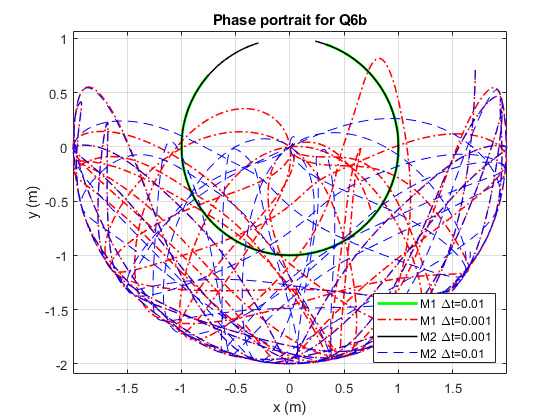

clear
clc
format long


data001=readmatrix('output-0.01.txt');
data0001=readmatrix('output-0.001.txt');

x1001=data001(:,2);
y1001=data001(:,3);
x2001=data001(:,4);
y2001=data001(:,5);

x10001=data0001(:,2);
y10001=data0001(:,3);
x20001=data0001(:,4);
y20001=data0001(:,5);

a=figure;
plot(x1001,y1001,'g','Linewidth',2)
grid on
axis equal
hold on
plot(x2001,y2001,'-.r','Linewidth',1.15)
plot(x10001,y10001,'k','Linewidth',1.15)
plot(x20001,y20001,'--b')
xlabel('x (m)')
ylabel('y (m)')
title('Phase portrait for Q6b')
legend('M1 \Deltat=0.01','M1 \Deltat=0.001','M2 \Deltat=0.001','M2 \Deltat=0.01','Location','southeast')
hold off
saveas(a,fullfile('C:\Users\lucam\MATLAB Drive\Published\Computing coursework\Grafici\Q6\Q6b','Q6b.png'))


%error final time
for i=0:3000
    deltax(i+1)=x2001(i+1)-x20001(10*i+1);
    deltay(i+1)=y2001(i+1)-y20001(10*i+1);
end
delta=sqrt(deltax.^2+deltay.^2);

%deltax=x2001(end)-x20001(end);
%deltay=y2001(end)-y20001(end);
%delta(2)=sqrt(deltax^2+deltay^2);

%deltax=x20001(end)-x200001(end);
%deltay=y20001(end)-y200001(end);
%delta(3)=sqrt(deltax^2+deltay^2);

%deltax=x20001(end)-x200001(end);
%deltay=y20001(end)-y200001(end);
%delta(4)=sqrt(deltax^2+deltay^2)

%earliest time error threshold 0.05 is 9.96 s

%iterations=[1000,10000,100000,1000000];

%plot(iterations,delta)